# Custom Styled Word List

This example shows how to style the following Word multilevel list by defining a new style in a custom Word template.

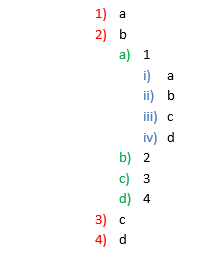

## Create Word Template

Import the DOM packages so that you do not have to use the fully qualified class names.

import mlreportgen.dom.*

Create a copy of the default Report Generator Word template.

Document.createTemplate("custom_list", "docx")

Start the Microsoft Word application and open the `custom_list.dotx` Word template. Do not double-click the custom_list.dotx template file. Double-clicking a template file creates a new Word document that is based on the template.

Click the Multilevel List arrow. Then click Define New List Style.

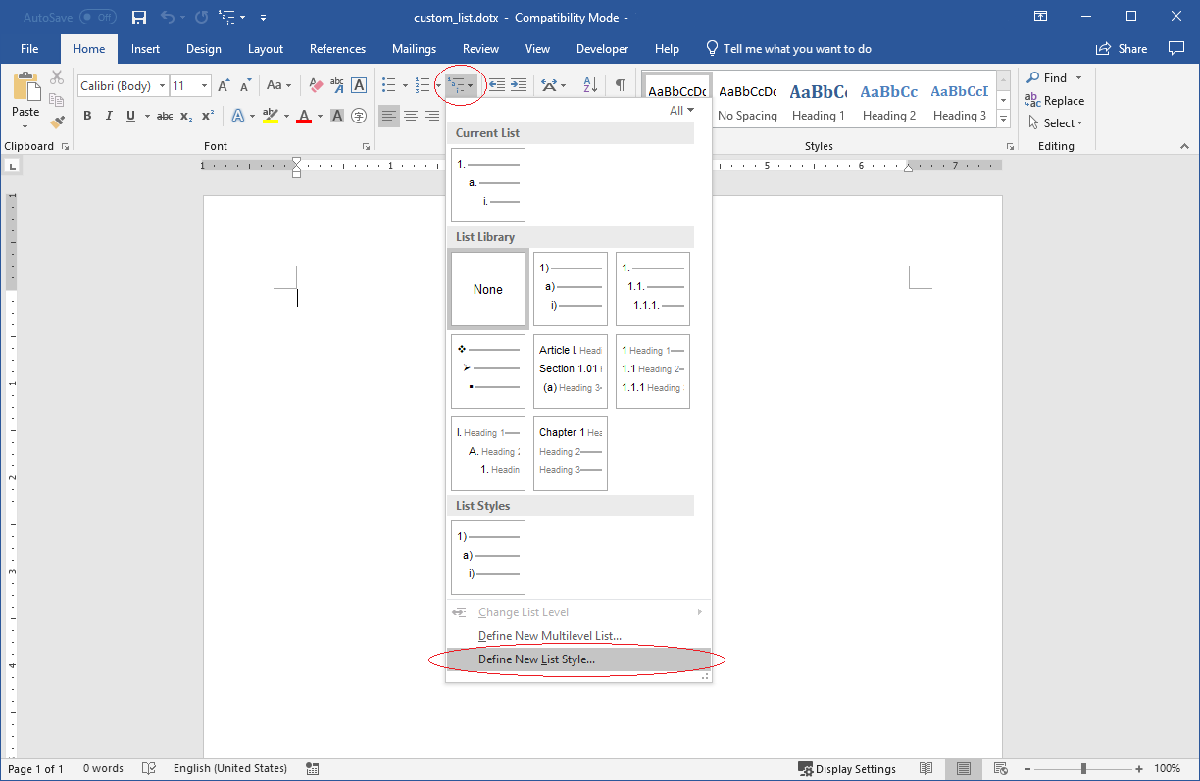

In the **Define New List Style** dialog box, enter a name for the style. For this example, use `MyColoredList` as the name. This name is used by the Report Generator to reference the custom multilevel list style.

Customize the multilevel list. For this example, the colors of first, second, and third levels, are red, green, and blue, respectively.

Before closing the dialog box, select **New documents based on this template**.

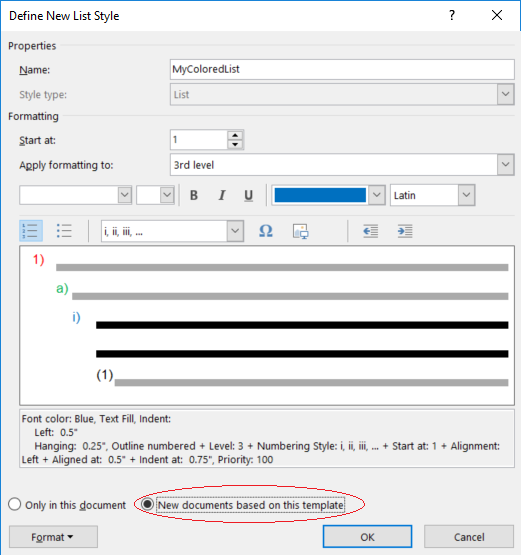

Closing the dialog creates a list. Delete this list, otherwise it will become boiler plate text for all new documents.

Save the template.

## Create Document

Create a Word document using the template that you created, custom_list.dotx.

The following code uses the template, custom_list_example.dotx, that is provided with this example. This template already specifies a colored list and is provided so that the example runs properly. If you are repeating the example steps, replace custom_list_example.dotx with custom_list.dotx.

d = Document("multilevel", "docx", "custom_list_example.dotx");

Create a multilevel list by using either an UnorderedList or an OrderedList object. The type of list DOM object does not matter. The style name controls the appearance of the list.

threeLevelCellArray = {
    'a', ...
    'b', ...
    { ...
        '1', ...
        { ...
            'a', ...
            'b', ...
            'c', ...
            'd' ...
        }, ...
        '2', ...
        '3', ...
        '4' ...
    }, ...
    'c', ...
    'd'};
list = UnorderedList(threeLevelCellArray);
list.StyleName = "MyColoredList";

Append the list to a `Document` object.

append(d, list);

Close and view the document.

close(d);
rptview(d);

*Copyright 2019 The MathWorks, Inc.*